# Support Vector Machines

This question uses a subset of the iris data - only the sepal widths and sepal lengths for the versicolor and virginica classes:

clear all;
load('binary.mat', 'examples', 'labels');

Use the whole dataset (without splitting) to train a standard Support Vector Machine (SVM) and visualise its linear decision boundary. Note that the dataset has already been z-score stadardised.

Marks are available for:

- An appropriate call to train an SVM on the whole dataset using default hyperparameters [2 marks]

- Generating a "grid" of testing data which spans the minimum and maximum value of each feature in the training dataset [8 marks]

- Using your trained SVM to classifiy the testing data you have generated [2 marks]

- Generating a scatter plot of your testing data, with each point colour-coded by the associated classification result [2 marks]

- Superimposing the original training data so that it is clearly visible [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

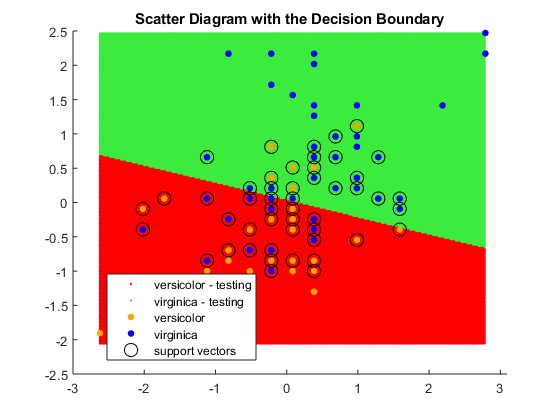

% add as many lines of code as you need below:
%1.
m = fitcsvm(examples, labels);
examples = table2array(examples);
%2. 
% Compute the scores over a grid
d = 0.02; % Step size of the grid
% [x1Grid,x2Grid] = meshgrid(min(examples(:,1)):d:max(examples(:,1)),...
%     min(examples(:,2)):d:max(examples(:,2)));
% 
% xGrid = [x1Grid(:),x2Grid(:)];  % The grid
% xGrid
grid = [];
for i=min(examples(:,1)):d:max(examples(:, 1))
    for j=min(examples(:,2)):d:max(examples(:, 2))
        newRow = [i j];
        grid = [grid; newRow];
    end
end
%3.
[predictions,scores1] = predict(m,grid); % The scores

figure;
hold on;
%4. 
hexColours = ['#FF0000';'#3CEC3C';'#ffa500';'#0000FF'];
cmap = hex2rgb(hexColours);
gscatter(grid(:, 1), grid(:, 2), predictions, cmap(1:2, :));
%5.
gscatter(examples(:,1),examples(:,2),labels, cmap(3:4, :));
plot(examples(m.IsSupportVector,1),...
    examples(m.IsSupportVector,2),'ko','MarkerSize',10);
    % Support vectors
% contour(x1Grid,x2Grid,reshape(scores1(:,2),size(x1Grid)),[0 0],'k');
    % Decision boundary
title('Scatter Diagram with the Decision Boundary')
hold off
legend({'versicolor - testing','virginica - testing','versicolor','virginica','support vectors'}, 'Location','Best')